## **This notebook is intended to create two toy JSSP Instances, one where LPT performs well while SPT performs bad, and another one where the contraire happens. **

**First let's create the LPT and SPT heuristics using the ruleBasedHH() environment (for guided steps go to HHtoH.mlx): **

clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

nbRules=1; 
targetProblem='job shop scheduling';

LPT=ruleBasedSelectionHH(nbRules,targetProblem);

SPT=ruleBasedSelectionHH(nbRules,targetProblem);


LPTmodel=[1 1 1 1 1 1];
SPTmodel=[1 1 1 1 1 2];

LPT.value=LPTmodel;
SPT.value=SPTmodel;

**Now let's create some toy instance (for guided steps go to UsingJSSPInstancem.mlx):**

m1=[1 2; 3 4] %processing times matrix

m1 =      1     2
     3     4


m2=[1 2; 2 1] %machine allocations matrix 

m2 =      1     2
     2     1



instanceData(:,:,1)=m1;
instanceData(:,:,2)=m2;

I1=JSSPInstance(instanceData); 

**It's time to test the instance and see if it fits one of the descriptions stated in the beginning: **

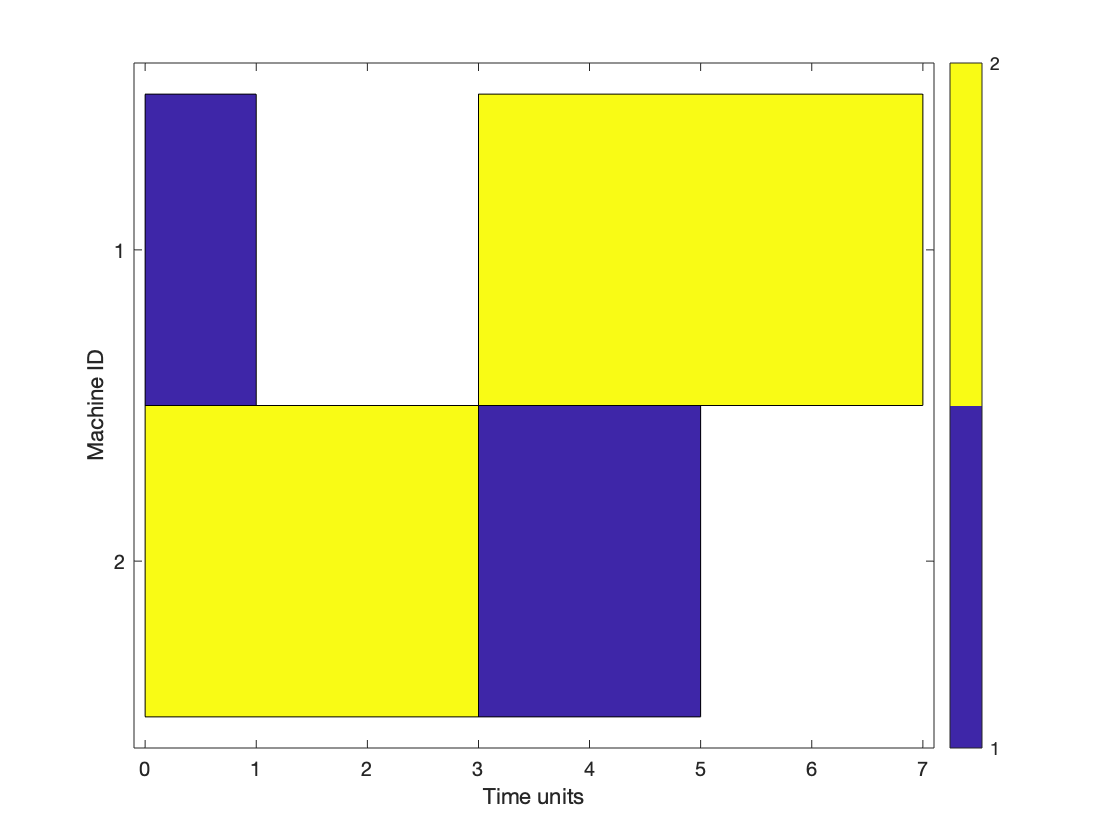

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


LPT.solveInstance(I1);
I1.solution.plot

I1.solution.makespan

ans = 7

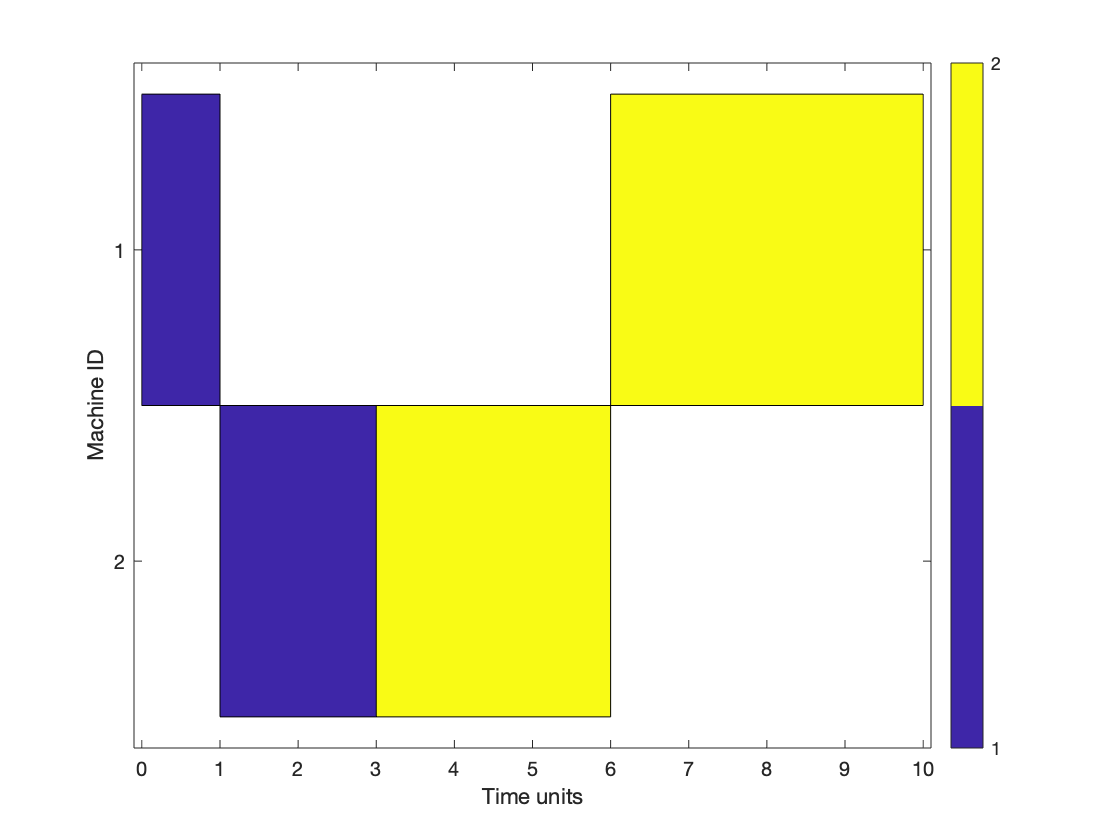

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


I1.reset; % let's return it to the original state (unsolved)
SPT.solveInstance(I1);
I1.solution.plot

**It looks that we find the first instance, it is solved well with LPT and not with SPT. Now let's try to find the contraire scenario:**

m1=[1 13; 5 8] %processing times matrix

m1 =      1    13
     5     8


m2=[1 2; 1 1] %machine allocations matrix 

m2 =      1     2
     1     1


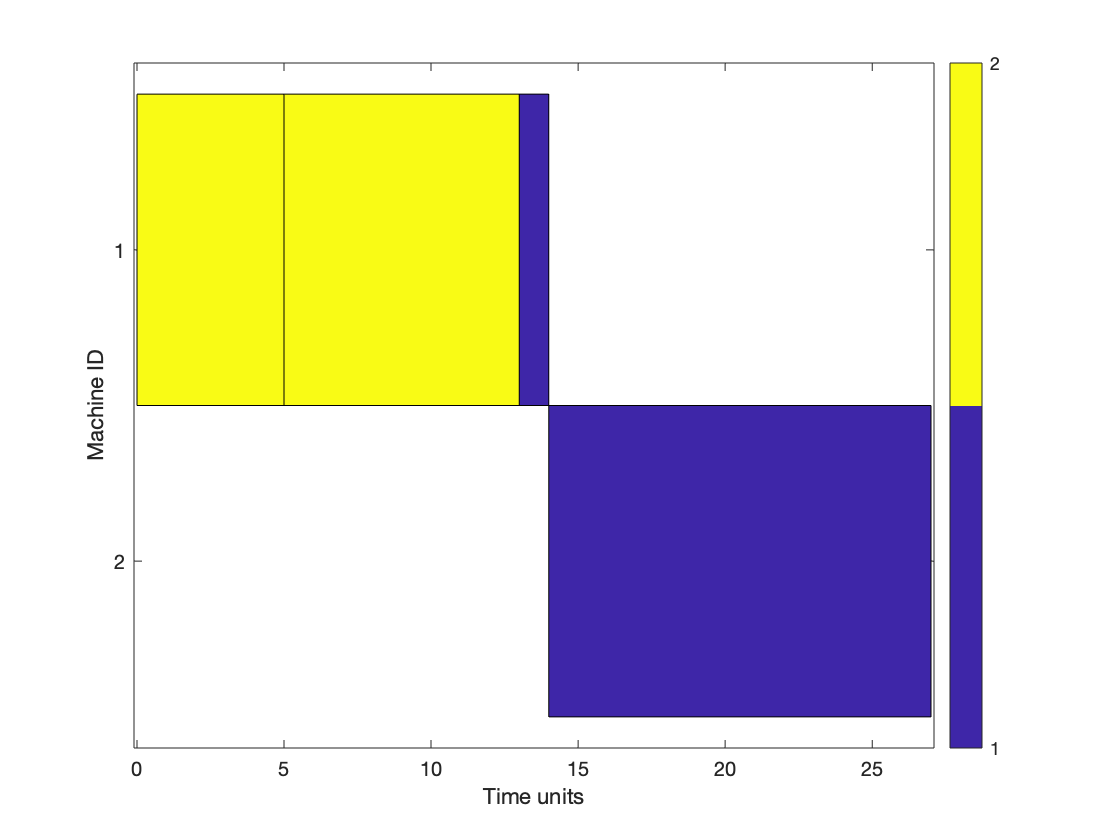

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties



instanceData(:,:,1)=m1;
instanceData(:,:,2)=m2;

I2=JSSPInstance(instanceData);

LPT.solveInstance(I2);
I2.solution.plot

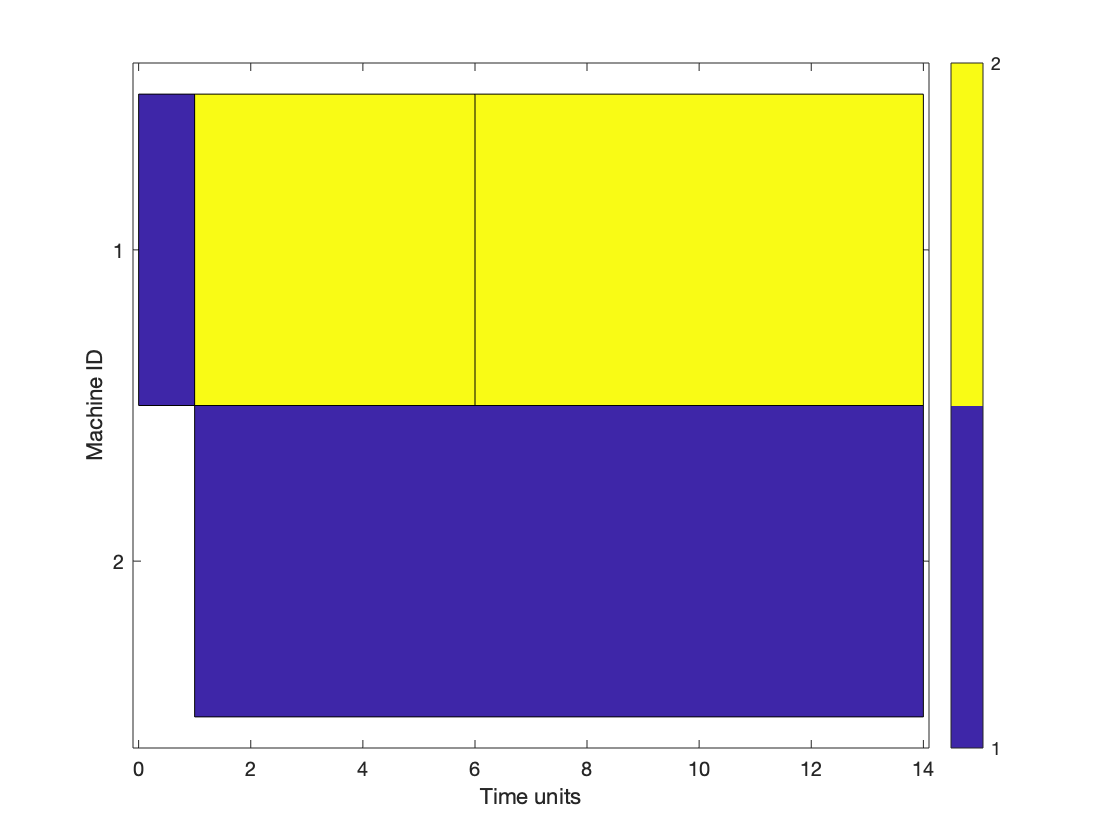

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


I2.reset;
SPT.solveInstance(I2);
I2.solution.plot

**And now we have an instance configuration that favors SPT and hinders LPT. Let's summarize: **

**I1 solved by LPT**

I1.reset
LPT.solveInstance(I1);
I1.solution.makespan

ans = 7

**I1 solved by SPT**

I1.reset
SPT.solveInstance(I1);
I1.solution.makespan

ans = 10

**I2 solved by LPT **

I2.reset
LPT.solveInstance(I2);
I2.solution.makespan

ans = 27

**I2 solved by SPT **

I2.reset
SPT.solveInstance(I2);
I2.solution.makespan

ans = 14

**This means that if LPT solved both instances the makespan accumulation will result in 34. **

**On the other hand, if SPT solved both instances the makespan accumulation will result in 24. **

**However, if only a method could exist that it includes the two heuristics and decided to select LPT to solved I1 and SPT to solved I2, the makespan accumulation will result in 21... **

%let's save the instances and heuristics for further experimentation
save('Exp1_I1','I1')
save('Exp1_I2','I2')
save('LPT','LPT')
save('SPT','SPT')